clear all
%the Stoker-King model 

colorCode = ["#EDB120", "#FF0000", "#0000FF"];

%Assign initial conditions
V0 = 1;
H0 = 100;
%Assign parameters
a = 4 * 10^-6;%infection rate
Ttotal = 36000;%run time
Tdelta = 1000;%time step

%Analytical solution
t_anal = 0:0.001:Ttotal; %start with 0 day
V_anal = (H0+V0)*V0./(V0+H0*exp(-a*(V0+H0)*(t_anal-t_anal(1))));

%predefine result matrix for each method
size = Ttotal/Tdelta + 1;
t = zeros(1,size);
V_RK = zeros(1,size);
V_FE = zeros(1,size);
V_BE = zeros(1,size);
%assign initial V
V_RK(1) = V0; %RK4
V_FE(1) = V0; %Forward Euler
V_BE(1) = V0; %Backward Euler

%Forward Euler
t(1) = 0; %start with 0 day
n = 1;
tic
while t(n)< Ttotal
    %forward Euler
    deriV = a * (H0 + V0 - V_FE(n)) * V_FE(n);
    V_FE(n+1) = V_FE(n) + Tdelta * deriV;

    t(n+1) = t(n) + Tdelta;
    n = n+1;
end
timeFE = toc

timeFE = 0.0027

%RK4
t = zeros(1,size);
t(1) = 0; %start with 0 day
n = 1;
tic
while t(n)< Ttotal

    A = Tdelta * (a * (H0 + V0 - V_RK(n)) * V_RK(n));
    B = Tdelta * (a * (H0 + V0 - (V_RK(n) + 0.5 * A)) * (V_RK(n) + 0.5 * A));
    C = Tdelta * (a * (H0 + V0 - (V_RK(n) + 0.5 * B)) * (V_RK(n) + 0.5 * B));
    D = Tdelta * (a * (H0 + V0 - (V_RK(n) + C)) * (V_RK(n) + C));
    V_RK(n+1) = V_RK(n) + (A + 2*B + 2*C + D) / 6;

    t(n+1) = t(n) + Tdelta;
    n = n + 1;
end
timeRK = toc

timeRK = 0.0031

%RKF45
tic
tspan = [0 Ttotal]

tspan =            0       36000


[t_45,V_45] = ode45(@(t_45,V_45) a * (H0 + V0 - V_45) * V_45,tspan,V0);
time45 = toc

time45 = 0.3490

%Backward Euler
t = zeros(1,size);
t(1) = 0; %start with 0 day
n = 1;
tic

while t(n)< Ttotal

   %Newton-Raphson method
    syms VNew
    f = (VNew-V_BE(n))/Tdelta - a * (H0+V0-VNew) * VNew;
    grad = diff(f);
    epsilon = 10^-6;
    Guess = V_BE(n);
    for i = 1:100
        f0 = vpa(subs(f,VNew,Guess));
        f1 = vpa(subs(grad,VNew,Guess));
        y = Guess-f0/f1;
        err = abs(y-Guess);
        if err < epsilon
            break
        end
        Guess = y;
    end
    clear VNew

    V_BE(n+1) = y;
    t(n+1) = t(n) + Tdelta;
    n = n + 1;
end

timeBE = toc

timeBE = 1.3841

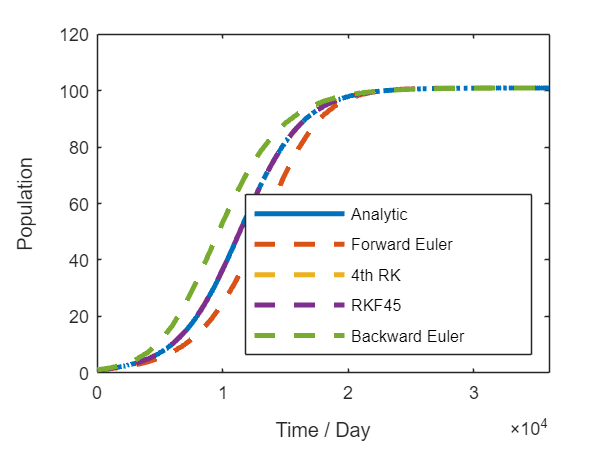

plot(t_anal,V_anal,'-',t,V_FE,'--',t,V_RK,'--',t_45,V_45,'--',t,V_BE,'--',LineWidth=2.5)
hold on
%scatter(t,V_RK)
%ylim([0 11000])
xlabel('Time / Day')
ylabel('Population')
xlim([0 Ttotal])
legend('Analytic','Forward Euler','4th RK','RKF45','Backward Euler',Location='southeast')
hold off

%{
V0test = [0,1,5,10:10:100];
H0test = [0,1,5,10:10:100];
t = zeros(1,size);
t(1) = 0; %start with 0 day
n = 1;
H = zeros(length(V0test)*length(H0test),size)
V = zeros(length(V0test)*length(H0test),size)
P = 1;
for j = 1:length(H0test)
    H0 = H0test(j);
    for i = 1:length(V0test)
        t = zeros(1,size);
        t(1) = 0;
        n = 1;
        V_RK = zeros(1,size);
        V0 = V0test(i);
        V_RK(1) = V0;

        while t(n)< Ttotal

            A = Tdelta * (a * (H0 + V0 - V_RK(n)) * V_RK(n));
            B = Tdelta * (a * (H0 + V0 - (V_RK(n) + 0.5 * A)) * (V_RK(n) + 0.5 * A));
            C = Tdelta * (a * (H0 + V0 - (V_RK(n) + 0.5 * B)) * (V_RK(n) + 0.5 * B));
            D = Tdelta * (a * (H0 + V0 - (V_RK(n) + C)) * (V_RK(n) + C));
            V_RK(n+1) = V_RK(n) + (A + 2*B + 2*C + D) / 6;

            t(n+1) = t(n) + Tdelta;
            n = n + 1;
        end
        V(P,:) = V_RK;
        H(P,:) = H0 + V0 - V(P,:);
        P=P+1;
    end
end
quiver(H,V)
%}

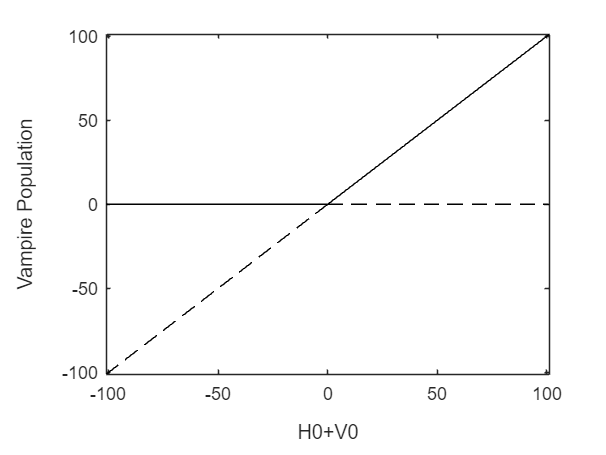

Ptot_posi = [0:0.1:101];
Ptot_nega = [-101:0.1:0];
V_posi = Ptot_posi;
V_nega = Ptot_nega;
plot(Ptot_posi,V_posi,'k-')
hold on
plot(Ptot_nega,V_nega,'k--')
line([0,101],[0,0],'Color','black','LineStyle','--')
line([-101,0],[0,0],'Color','black','LineStyle','-')
xlabel('H0+V0')
ylabel('Vampire Population')

xlim([-101,101])
ylim([-101,101])
hold off